# Comparación de controladores discretos

## Max Pacheco Ramírez - A01552369


$$G_p \left(z\right)=\frac{10z+5}{z-0\ldotp 2}z^{-1}$$


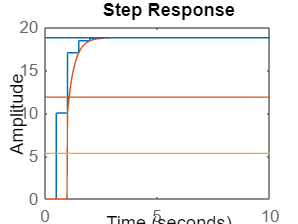

T = 0.5;
z = tf('z',T);
Gpz = (10*z+5)/(z-0.2)*z^-1;
Gpz_num = Gpz.Numerator{1,1};
Gpz_den = Gpz.Denominator{1,1};
step(Gpz)

theta = 1;
Gz = (10*z+5)/(z-0.2);
Gs = d2c(Gz, 'zoh');
Gps = tf([10,60.35],[1,3.219],'inputdelay',theta);
hold on
step(Gps)
plot(linspace(0,10),linspace(0,10).*0+60.35/3.219);
plot(linspace(0,10),linspace(0,10).*0+60.35/3.219*0.632);
plot(linspace(0,10),linspace(0,10).*0+60.35/3.219*0.283);

Caso 1. Deadbeat


$$G_c \left(z\right)=\left(\frac{1}{G_p \left(z\right)}\right)\left(\frac{1}{z^k -1}\right)$$


k = 1;
Gcz_db = 1/(Gpz*(z^k - 1));
Gcz_db_num = Gcz_db.Numerator{1,1};
Gcz_db_den = Gcz_db.Denominator{1,1};

Caso 2. PID (Criterios Integrales$\to$IAE)


$$G_c \left(z\right)=K_{\textrm{pz}} +\frac{K_{\textrm{iz}} }{1-z^{-1} }+K_{\textrm{dz}} \left(1-z^{-1} \right)$$


a = 1.086;
b = -0.869;
c = 0.74;
d = -0.13;
e = 0.348;
f = 0.914;


$$G_p \left(s\right)=\frac{{Ke}^{-\theta s} }{\tau s+1}$$


tau = 0.111;
K = 18.75;
theta_pid = 0.5;

Kp = (1/K) * (a*(theta_pid/tau)^b);
Taui = (tau) / (c + d*(theta_pid/tau));
Taud = (tau) * (e * (theta_pid/tau)^f);

Kpz = Kp - (Kp * T)/(2*Taui);
Kiz = (Kp*T)/Taui;
Kdz = (Kp*Taud)/T;

Caso 3. Controlador de Dahlin


$$G_c \left(z\right)=\left(\frac{1}{G_p \left(z\right)}\right)\left(\frac{T\left(z\right)}{1-T\left(z\right)}\right)$$


Requerimiento (dinámica de primer orden):


$$T\left(s\right)=\frac{1}{\tau s+1}e^{-\textrm{Ls}}$$



$$L=\textrm{kT}$$



$$\tau =3$$


Transformación de tiempo muerto:


$$Z\left\lbrace e^{-\textrm{Ls}} \right\rbrace =z^{-k}$$


Ts = tf([1],[3,1]);
Tz = c2d(Ts,T,'zoh')*(z^-k);

Gcz_dahlin = (1/Gpz)*(Tz/(1-Tz));
Gcz_num_dahlin = Gcz_dahlin.Numerator{1,1};
Gcz_den_dahlin = Gcz_dahlin.Denominator{1,1};